nvar = 4;
lb = [1 1 1 1];
ub = [10 10 10 10];
SLL_level_dB = -40;   %ΑΛΛΑΞΕ ΤΑ dB
SLL_level = 10^(SLL_level_dB/20);

gamultiobj stopped because the average change in the spread of Pareto solutions is less than options.FunctionTolerance.


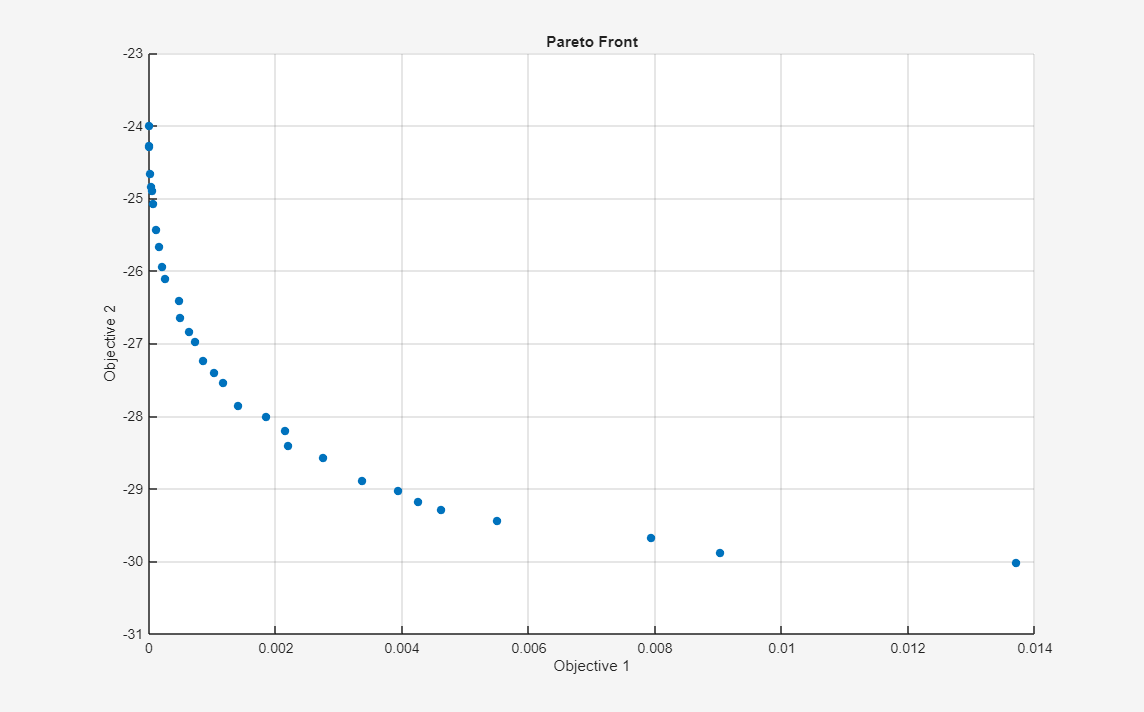

% Pass fixed parameters to objfun
objfun = @(p)SLL_error_and_D(p,SLL_level);

% Set nondefault solver options
options = optimoptions("gamultiobj","PopulationSize",100,"PlotFcn",...
    "gaplotpareto");

% Solve
[solution,objectiveValue] = gamultiobj(objfun,nvar,[],[],[],[],lb,ub,[],[],...
    options);


% Clear variables
clearvars objfun options


function F = SLL_error_and_D(p, SLL_target)
    I0 = 1;
    N = 10;


    I1 = p(1);
    I2 = p(2);
    I3 = p(3);
    I4 = p(4);

    I = [I0; I1; I2; I3; I4; I4; I3; I2; I1; I0];

    lambda = 1;
    d = lambda/2;
    delta = 0;
    k = 2*pi/lambda;
    
    theta = linspace(0, pi/2, 90);
    psi = k*d*cos(theta) + delta;
    
    A = zeros(size(theta));
    for n = 0:(N-1)
        A = A + I(n+1)*exp(1j*n*psi);
    end

    A = abs(A);
    A = A / max(A);
    
   
    [peaks, locs] = findpeaks(A);
    SLL_error = mean((peaks-SLL_target).^2);
    
    K = 0; L = 0;
    for n = 0:(N-1)
        K = K + I(n+1);
        for m = 0:N-1
            if n==m
                L = L + I(n+1)*I(m+1); %για την περίπτωση sin(0)/0 = 1
            else
                L = L + I(n+1)*I(m+1)*sin((n-m)*pi/(n-m));
            end
        end
    end
    D = pi*K^2 / L;

    F = [SLL_error, -D];

end
